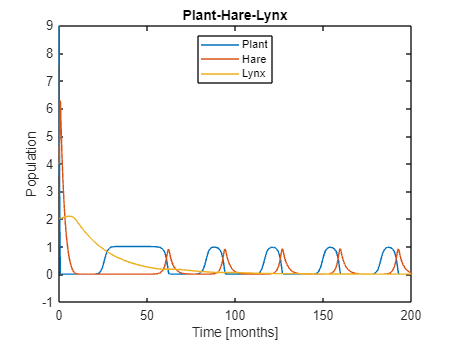

t0 = 0;                 	% start time of simulation [in months]
tfinal = 200;                % end time of simulation [in months]
y0= [9 4 2];               % initial state i.e. number of plants, hares and lynxs at t=0
tspan = [t0 tfinal];        % time span defined by the start and end times of the simulation [in months]
a1 = 8;               % predation success rate parameter ("how likely that the hare dies if it meets a lynx")
a2= 0.5;              % lynx population increase rate due to predation on tuna ("how much food a linx gets out of eating a hare")
b1= 6;
b2= 8;
d1= 0.4;
d2=0.05;

[t,y] = ode23(@(t,y) plants_hare_lynx_(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);

% plotting the population over time
figure("Name",'hare-lynx');
plot(t,y)
title('Plant-Hare-Lynx');
xlabel('Time [months]');
ylabel('Population');
legend('Plant','Hare','Lynx','Location','North');

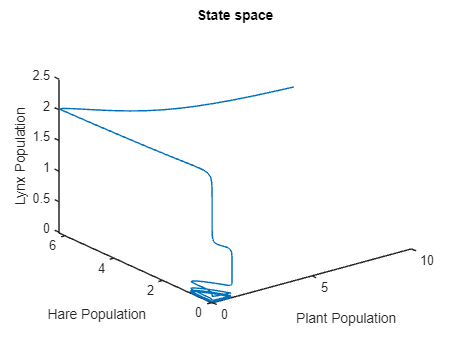

figure("Name",'State space')
plot3(y(:,1),y(:,2),y(:,3))
title('State space')
xlabel('Plant Population')
ylabel('Hare Population')
zlabel('Lynx Population')

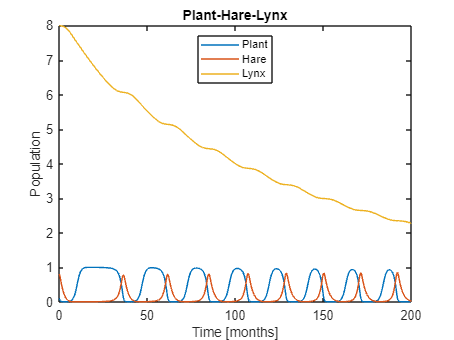

%Scenario 1: The system exhibits stable oscillations with a 
% periodicity of approximately 70 months.

t0 = 0;                 	% start time of simulation [in months]
tfinal = 200;                % end time of simulation [in months]
y0= [0.1 0.8 8];               % initial state i.e. number of plants, hares and lynxs at t=0
tspan = [t0 tfinal];        % time span defined by the start and end times of the simulation [in months]
a1= 5;               % predation success rate parameter ("how likely that the hare dies if it meets a lynx")
a2= 0.1;              % lynx population increase rate due to predation on tuna ("how much food a linx gets out of eating a hare")
b1= 3;              %the saturation point for plants consumption by hares.  
b2= 10;             % the saturation point for hare consumption by lynxes.
                    %This model presents period oscillation of about 40-50
                    %months, so it is not stable. As the population of hare
                    %increases, the lynxes have more food to survive and
                    %reproduce. When reaching the highest saturation point,
                    %the lynxes put more pressure on hare reproduction,
                    %leading to their decrease. Their decrease results in a
                    %following increase in plant mass growth. 
                
               
              
d1= 0.4;            %death rate of hares.
d2= 0.01;           %death rate of lynxes.

[t,y] = ode23(@(t,y) plants_hare_lynx_(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);

% plotting the population over time
figure("Name",'hare-lynx');
plot(t,y)
title('Plant-Hare-Lynx');
xlabel('Time [months]');
ylabel('Population');
legend('Plant','Hare','Lynx','Location','North')

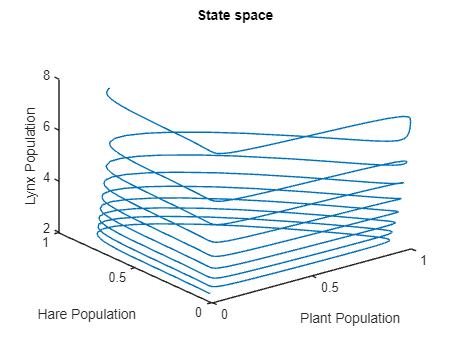

figure("Name",'State space')
plot3(y(:,1),y(:,2),y(:,3))
title('State space')
xlabel('Plant Population')
ylabel('Hare Population')
zlabel('Lynx Population')